Instantiating...


Forward solution... 

Adjoint solution... 

complete.


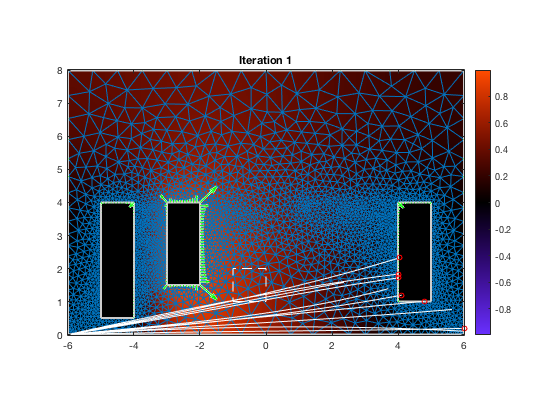

Instantiating...


Forward solution... 

Adjoint solution... 

complete.


Instantiating...


Forward solution... 

Adjoint solution... 

complete.


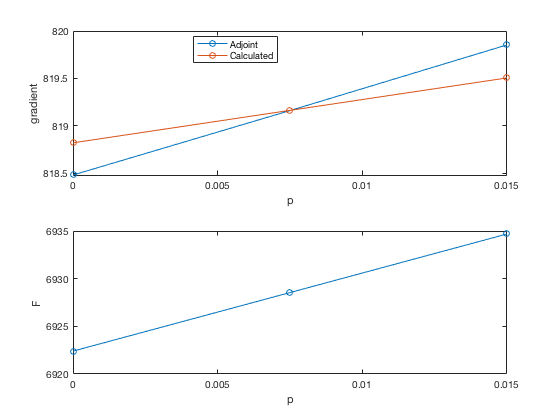

%% Contour points (oriented correctly) and mesh size parameters

Lx = 6;
Ly = 8;
rAperture1 = 0.5;
rAperture2 = 1.5;
rAperture3 = 1;
d = 4;

isAxisymmetric = 1;

%%

N_field = 3;
N_geom = 2;
N_quad = N_field + isAxisymmetric; % there is a reason for this

p0 = [0,0,0,0,0,0,0,0]';
%s = 2; % mesh scale
s = 2e-1;

geom2d = ParameterizedGeometry2D();
geom2d.addContour(@(p) [-Lx, 0, Lx, Lx, 0, -Lx], @(p) [0, 0, 0, Ly, Ly, Ly], s*[0.5, 4, 0.5, 4, 4, 4], 1, 1:6);
geom2d.addContour(@(p) [-Lx+1, -Lx+2, -Lx+2, -Lx+1], @(p) [rAperture1, rAperture1, Ly-d, Ly-d]+p(5:8)', s*0.5, 2, 1:4);
geom2d.addContour(@(p) [-Lx+3, -Lx+4, -Lx+4, -Lx+3]+p(1:4)', @(p) [rAperture2, rAperture2, Ly-d, Ly-d], s*0.5, 3, 1:4);
geom2d.addContour(@(p) [Lx-2, Lx-1, Lx-1, Lx-2], @(p) [rAperture3, rAperture3, Ly-d, Ly-d], s*0.5, 2, 1:4);

fem = FEMInterface(geom2d, N_field, N_geom, N_quad, isAxisymmetric);
fem.setNeumann(1, @(p,x,y) 0.0);
fem.setDirichlet(2, @(p,x,y) 0.0);
fem.setDirichlet(3, @(p,x,y) 1.0);
fem.setFreeCharge(@(p,x,y) 0.0);

%%

[femProblem, dDirichlet_dp, dnx_dp, dny_dp] = fem.instantiateProblem(p0);

%% Sensitivity

p0 = [0,0,0,0,0,0,0,0]';
iParamToVary = 3;

%deltas = linspace(0.0, 0.15, 6);

deltas = linspace(0.0, 0.015, 3);
%deltas = linspace(0.0, 2.5, 10);
%deltas = deltas(2:end);

Fs = 0*deltas;
DFs = 0*deltas;
ps = 0*deltas;

for nn = 1:length(deltas)
    p = p0;
    p(iParamToVary) = p(iParamToVary) + deltas(nn);
    ps(nn) = p(iParamToVary);
    
    fprintf('Instantiating...\n');
    
    DO_ADJUST_MESH = 1;  % Lars pay attention to this!!!!
    
    if DO_ADJUST_MESH
        [femProblem, dDirichlet_dp, dnx_dp, dny_dp] = fem.adjustProblem(p);
    else
        [femProblem, dDirichlet_dp, dnx_dp, dny_dp] = fem.instantiateProblem(p);
    end
    xyGeomNodes = femProblem.poi.tnMesh.xyNodes;
    geometry = fem.instantiatedGeom.geometry;
    
    measBox = [-1, 1, 0, 2]; %[-0.5, -0.5, 0.5, 0.5];
    %measNxy = [20, 20];
    measNxy = [100, 100];
    
    %measBox = [-5, 0, 5, 0.4];
    %measNxy = [2, 2];
    
    objFun = @(u_Cartesian) sum(u_Cartesian(:));
    DobjFun = @(u_Cartesian) ones(size(u_Cartesian));
    
    fprintf('Forward solution... ');
    femProblem.solveCartesian(measBox(1:2), measBox(3:4), measNxy);
    F = objFun(femProblem.uCartesian);
    
    
    fprintf('Adjoint solution... ');
    %femProblem.solveAdjoint(DobjFun, DoutI);
    femProblem.solveAdjointCartesian(DobjFun(femProblem.uCartesian));
    fprintf('complete.\n');
    
    % Sensitivity to parameters
    dFdp = femProblem.dF_dxy(:,1)' * dnx_dp + femProblem.dF_dxy(:,2)' * dny_dp ...
        + femProblem.dF_dDirichlet * dDirichlet_dp;
    
    Fs(nn) = F; %femProblem.F;
    DFs(nn) = dFdp(iParamToVary);
    
    % Create some fake trajectories
    numT = 100;
    numParticles = 10;
    [xTraj, yTraj] = fakeTrajectories(-Lx, 0, Lx, 1, numT, numParticles);
    yTraj = abs(yTraj); % implement mirroring
    
    % Find the splat time of EACH trajectory
    splatTimeMatrix = calculateSplat(xTraj, yTraj, geometry.vertices, geometry.contourVertexIndices);
    [idxSplatTraj,~,idxSplatTime] = find(splatTimeMatrix);
    % idxSplatTraj = indices of trajectories that splatted
    % idxSplatTime = timesteps of first splatq
    
    figure(1); clf
    xCoarse = linspace(-Lx, Lx, 200);
    yCoarse = linspace(0, Ly, 200);
    u = femProblem.poi.tnMesh.rasterizeField(femProblem.u, xCoarse, yCoarse);
    imagesc_centered(xCoarse, yCoarse, u'); axis xy image; colorbar
    colormap orangecrush
    hold on
    femProblem.poi.tnMesh.plotMesh();
    ax = axis();
    plot([geometry.vertices(geometry.lines(:,1),1), geometry.vertices(geometry.lines(:,2),1)]', ...
        [geometry.vertices(geometry.lines(:,1),2), geometry.vertices(geometry.lines(:,2),2)]', 'color', [0.8 0.8 0.8], 'linewidth', 2)
    
    % Plot geometry
    %id = ':';
    id = find(fem.instantiatedGeom.getGeomNodeLines);
    quiver(xyGeomNodes(id,1), xyGeomNodes(id,2), femProblem.dF_dxy(id,1), femProblem.dF_dxy(id,2), 'w-', 'linewidth', 2)
    quiver(xyGeomNodes(id,1), xyGeomNodes(id,2), femProblem.dF_dxy(id,1), femProblem.dF_dxy(id,2), 'g-', 'linewidth', 1)
    plot(measBox([1,3,3,1,1]), measBox([2,2,4,4,2]), 'w--');
    axis(ax);
    title(sprintf('Iteration %i', nn));
    
    % Plot trajectories and splats
    %plot(xTraj, yTraj, 'w-');
    for pp = 1:size(xTraj,2)
        if splatTimeMatrix(pp) ~= 0
            plot(xTraj(1:splatTimeMatrix(pp),pp), yTraj(1:splatTimeMatrix(pp),pp), 'w-');
        else
            plot(xTraj(:,pp), yTraj(:,pp), 'w-');
        end
    end
    ii = sub2ind(size(xTraj), idxSplatTime, idxSplatTraj);
    plot(xTraj(ii), yTraj(ii), 'ro', 'markersize', 5);
    
    
    figure(2); clf
    subplot(2,1,1);
    plot(ps(1:nn), DFs(1:nn), 'o-');
    %yl = ylim;
    hold on
    if nn >= 2
        df_meas = gradient(Fs(1:nn), deltas(1:nn));
        plot(ps(1:nn), df_meas, 'o-');
        %ylim(yl);e
    end
    xlabel('p')
    ylabel('gradient')
    legend('Adjoint', 'Calculated', 'location', 'best');

    subplot(2,1,2);
    plot(ps(1:nn), Fs(1:nn), 'o-');
    xlabel('p')
    ylabel('F')

    pause(0.01)
end